%% Clear workspace
clear all; close all; clc;

%% Define constants and parameters
R_earth = 6371e3; % Earth radius in meters
h = 500e3; % Satellite orbit height in meters
f = 2e9; % Frequency in Hz
l_air = 1; % Air absorption (assumed negligible at 2 GHz) No air absorption
beta = 2.3;
mu_LoS_dB = 0; % Excess path-loss parameters (in dB)
mu_LoS = mu_LoS_dB;

sigma_LoS_dB = 2.8; % in dB
sigma_LoS = sigma_LoS_dB;

mu_NLoS_dB = 12; % in dB
mu_NLoS = mu_NLoS_dB;

sigma_NLoS_dB = 9; % in dB
sigma_NLoS = sigma_NLoS_dB;

a = 3.68; % Terrestrial path-loss exponent
P_dBm = 23; % Device transmit power (EIRP) in dBm
P = 10^((P_dBm - 30) / 10); % Device transmit power (EIRP) in Watts
psi = 2 * pi; % Satellite beamwidth (assume isotropic) in radians
gamma_o_dB = -20; % SINR threshold in dB
gamma_o = 10^(gamma_o_dB / 10); % linear
W_b_dBm = -117; % Noise power at BS and satellite receivers in dBm
W_b = 10^((W_b_dBm - 30) / 10); % in Watts
W_s_dBm = -130; % in dBm
W_s = 10^((W_s_dBm - 30) / 10); % in Watts
kappa_b_dB = -20; % Interference mitigation factors in dB
kappa_b = 10^(kappa_b_dB / 10); % linear
kappa_s_dB = -20; % in dB
kappa_s = 10^(kappa_s_dB / 10); % linear
D = 0.01; % Transmission duty cycle 1%

c = 3e8; % Speed of light in m/s
lambda = c / f; % Wavelength
l_o = (c / (4 * pi * f))^2; % Path gain constant

alpha = R_earth / (R_earth + h); % Alpha parameter
rho = log(10) / 10; % Conversion factor
b = 1;

%%
lambda_d = 1e-8; % Device density (devices per m^2)
Ns_list = [10, 100, 1000 ,10000]; % Number of satellites
bs_density_per_100km2 = logspace(0, 3, 50); % BS densities per 100 km^2
lambda_b_list = bs_density_per_100km2 / 1e8; % Convert BS densities to per m^2

p_c_analytic = zeros(length(Ns_list), length(lambda_b_list));
p_c_simulation = zeros(length(Ns_list), length(lambda_b_list));

% Number of Monte Carlo simulations
num_runs = 100;

% Simulation area dimensions
area_side_large = 100e3;  
area_large = area_side_large^2;

area_side_small = 10e3;  %(10 km x 10 km)
area_small = area_side_small^2;

area_radius_small = area_side_small / 2; % Radius of the smaller area
area_radius_large = area_side_large / 2; % Radius of the larger area

%% Compute average satellite interference power (assumed constant in simulation)
I_s_avg = compute_I_s_avg(P, l_o, R_earth, h, beta, mu_LoS_dB, sigma_LoS_dB, mu_NLoS_dB, sigma_NLoS_dB, D, lambda_d, kappa_s);

%% Loop over satellite constellation sizes
for idx_Ns = 1:length(Ns_list)
    Ns = Ns_list(idx_Ns);
    fprintf('Processing Ns = %d\n', Ns);
    
    % Compute analytic satellite coverage probability p_s
    p_s = compute_p_s(Ns, P, gamma_o, W_s, l_o, R_earth, h, beta, mu_LoS_dB, sigma_LoS_dB, mu_NLoS_dB, sigma_NLoS_dB, D, lambda_d, kappa_s);
    
    % Loop over base station densities
    for idx_lb = 1:length(lambda_b_list)
        lambda_b = lambda_b_list(idx_lb);
        
        % Compute analytic terrestrial coverage probability p_b
        p_b = compute_p_b(lambda_b, P, gamma_o, W_b, l_o, a, D, lambda_d, kappa_b);
        
        % Compute hybrid coverage probability analytically
        p_c_analytic(idx_Ns, idx_lb) = 1 - (1 - p_s) * (1 - p_b);
        
        % Simulate the hybrid network
        coverage_count = 0;
        for run_idx = 1:num_runs
            % Simulate users and interferers in the large area
            num_users_large = poissrnd(lambda_d * area_large);
            num_bs_large = poissrnd(lambda_b * area_large);
            
            % Generate user positions in large area (interferers)
            [x_large, y_large] = generate_uniform_circle(num_users_large, area_radius_large);
            user_positions_large = [x_large, y_large];
            
            % Generate BS positions in large area
            [x_bs_large, y_bs_large] = generate_uniform_circle(num_bs_large, area_radius_large);
            bs_positions_large = [x_bs_large, y_bs_large];
            
            % Select users within the small central area for evaluation
            distances_to_center = sqrt(user_positions_large(:,1).^2 + user_positions_large(:,2).^2);
            users_in_small_area = distances_to_center <= area_radius_small;
            user_positions_small = user_positions_large(users_in_small_area, :);
            num_users_small = sum(users_in_small_area);
            
            if num_users_small == 0
                continue;
            end
            
            % Terrestrial link calculations
            success_b = false(num_users_small,1); % Initialize terrestrial success to false
            gamma_b = zeros(num_users_small,1);   % SINR at BS
            
            if num_bs_large > 0
                % For each user in the small area, find the nearest BS
                distances_bs = pdist2(user_positions_small, bs_positions_large);
                [min_distances_bs, bs_indices] = min(distances_bs, [], 2);
                r = min_distances_bs;
                % Compute path-loss and fading
                l_b = b * l_o * r.^(-a);
                g = exprnd(1, num_users_small, 1);
                S_b = P * g .* l_b;
                
                % Compute interference at BSs
                for u = 1:num_users_small
                    % Serving BS position
                    bs_pos = bs_positions_large(bs_indices(u), :);
                    % Interfering users (excluding the desired user)
                    interfering_users = [user_positions_large(1:end ~= u, :)];
                    num_interferers = size(interfering_users, 1);
                    % Interference initialization
                    I_b = 0;
                    for i = 1:num_interferers
                        % Interfering user activity
                        if rand < D
                            % Interfering user position
                            interferer_pos = interfering_users(i, :);
                            % Distance to serving BS
                            r_i = norm(interferer_pos - bs_pos);
                            % Path-loss
                            l_bi = b * l_o * r_i^(-a);
                            % Fading
                            h_i = exprnd(1);
                            % Interference power
                            I_bi = P * h_i * l_bi * kappa_b;
                            % Accumulate interference
                            I_b = I_b + I_bi;
                        end
                    end
                    % SINR at BS
                    gamma_b(u) = S_b(u) / (I_b + W_b);
                    % Determine success
                    success_b(u) = gamma_b(u) >= gamma_o;                    
                end
            else
                success_b = false(num_users_small,1); % No BSs, so terrestrial link fails
            end
            
            %% Satellite link calculations             
            % Generate satellite positions
            cos_theta_s = 2 * rand(Ns,1) - 1;
            theta_s = acos(cos_theta_s);
            phi_s = 2 * pi * rand(Ns,1);
            
            x_s = (R_earth + h) * sin(theta_s) .* cos(phi_s);
            y_s = (R_earth + h) * sin(theta_s) .* sin(phi_s);
            z_s = (R_earth + h) * cos(theta_s);
            
            % User positions in 3D (users in small area)
            x_u = user_positions_small(:,1);
            y_u = user_positions_small(:,2);
            z_u = R_earth * ones(num_users_small,1);
            
            % Compute delta_x, delta_y, delta_z
            delta_x = bsxfun(@minus, x_s, x_u'); % Ns x num_users_small
            delta_y = bsxfun(@minus, y_s, y_u');
            delta_z = bsxfun(@minus, z_s, z_u');
            
            % Compute v_us_norm
            v_us_norm = sqrt( delta_x.^2 + delta_y.^2 + delta_z.^2 ); % Ns x num_users_small
            
            % Compute cos_phi_prime
            cos_phi_prime = delta_z ./ v_us_norm; % Ns x num_users_small
            
            % Compute phi_prime
            phi_prime = acos( cos_phi_prime ); % Ns x num_users_small
            
            % For each user, find the satellite with minimum phi_prime
            [phi_min, sat_indices] = min(phi_prime, [], 1); % 1 x num_users_small
            
            % Extract distances d(u)
            indices = sub2ind(size(v_us_norm), sat_indices, 1:num_users_small);
            d_u = v_us_norm(indices)'; % Column vector of distances
            
            % Get serving satellite positions
            x_s_u = x_s(sat_indices);
            y_s_u = y_s(sat_indices);
            z_s_u = z_s(sat_indices);
            
            % Compute cos_phi(u)
            cos_phi = (x_u .* x_s_u + y_u .* y_s_u + z_u .* z_s_u ) / ( R_earth * ( R_earth + h ));
            
            % Compute phi(u)
            phi = acos(cos_phi);
            
            % Compute path-loss l(u)
            l_u = l_o * l_air ./ d_u.^2;
            
            % Compute tan_phi_prime
            tan_phi_prime = tan(phi_min'); % Column vector
            % Compute pLoS(u)
            pLoS = exp(- beta * tan_phi_prime);
            pLoS = min(max(pLoS, 0), 1);
            % Generate random numbers to determine LoS/NLoS
            rand_vals = rand(num_users_small, 1);
            is_LoS = rand_vals <= pLoS;
            
            % Generate ζ(u)
            zeta = zeros(num_users_small, 1);
            % For LoS users
            zeta(is_LoS) = 10.^(-(mu_LoS_dB + sigma_LoS_dB * randn( sum(is_LoS ), 1))/10);
            % For NLoS users
            zeta( ~is_LoS ) = 10.^(-(mu_NLoS_dB + sigma_NLoS_dB * randn(sum(~is_LoS ), 1 ) ) / 10 );
            
            % Compute S_s(u)
            S_s = P * l_u .* zeta;
            
            % Compute gamma_s(u)
            gamma_s = S_s ./ ( I_s_avg + W_s );
            
            % Determine success_s(u)
            success_s = gamma_s >= gamma_o;
            
            % Hybrid coverage
            success = success_s | success_b;
            coverage_count = coverage_count + sum(success) / num_users_small;
        end
        % Average coverage probability from simulation
        p_c_simulation(idx_Ns, idx_lb) = coverage_count / num_runs;
        fprintf('Ns = %d, lambda_b = %.4f, p_c_analytic = %.4f, p_c_simulation = %.4f\n', Ns, bs_density_per_100km2(idx_lb), p_c_analytic(idx_Ns, idx_lb), p_c_simulation(idx_Ns, idx_lb));
    end
end

Processing Ns = 10


Ns = 10, lambda_b = 1.0000, p_c_analytic = 0.1813, p_c_simulation = 0.2803
Ns = 10, lambda_b = 1.1514, p_c_analytic = 0.1946, p_c_simulation = 0.2567
Ns = 10, lambda_b = 1.3257, p_c_analytic = 0.2096, p_c_simulation = 0.2317
Ns = 10, lambda_b = 1.5264, p_c_analytic = 0.2264, p_c_simulation = 0.3042
Ns = 10, lambda_b = 1.7575, p_c_analytic = 0.2451, p_c_simulation = 0.2195
Ns = 10, lambda_b = 2.0236, p_c_analytic = 0.2660, p_c_simulation = 0.3277
Ns = 10, lambda_b = 2.3300, p_c_analytic = 0.2890, p_c_simulation = 0.2058
Ns = 10, lambda_b = 2.6827, p_c_analytic = 0.3144, p_c_simulation = 0.2658
Ns = 10, lambda_b = 3.0888, p_c_analytic = 0.3421, p_c_simulation = 0.4008
Ns = 10, lambda_b = 3.5565, p_c_analytic = 0.3722, p_c_simulation = 0.2392
Ns = 10, lambda_b = 4.0949, p_c_analytic = 0.4046, p_c_simulation = 0.4425
Ns = 10, lambda_b = 4.7149, p_c_analytic = 0.4392, p_c_simulation = 0.3342
Ns = 10, lambda_b = 5.4287, p_c_analytic = 0.4757, p_c_simulation = 0.3433
Ns = 10, lambda_b = 6.250

Processing Ns = 100


Ns = 100, lambda_b = 1.0000, p_c_analytic = 0.4508, p_c_simulation = 0.2125
Ns = 100, lambda_b = 1.1514, p_c_analytic = 0.4597, p_c_simulation = 0.4408
Ns = 100, lambda_b = 1.3257, p_c_analytic = 0.4698, p_c_simulation = 0.3167
Ns = 100, lambda_b = 1.5264, p_c_analytic = 0.4810, p_c_simulation = 0.4133
Ns = 100, lambda_b = 1.7575, p_c_analytic = 0.4936, p_c_simulation = 0.3658
Ns = 100, lambda_b = 2.0236, p_c_analytic = 0.5076, p_c_simulation = 0.3737
Ns = 100, lambda_b = 2.3300, p_c_analytic = 0.5231, p_c_simulation = 0.3283
Ns = 100, lambda_b = 2.6827, p_c_analytic = 0.5401, p_c_simulation = 0.3967
Ns = 100, lambda_b = 3.0888, p_c_analytic = 0.5587, p_c_simulation = 0.3800
Ns = 100, lambda_b = 3.5565, p_c_analytic = 0.5789, p_c_simulation = 0.4533
Ns = 100, lambda_b = 4.0949, p_c_analytic = 0.6006, p_c_simulation = 0.4108
Ns = 100, lambda_b = 4.7149, p_c_analytic = 0.6238, p_c_simulation = 0.3517
Ns = 100, lambda_b = 5.4287, p_c_analytic = 0.6483, p_c_simulation = 0.4010
Ns = 100, la

Processing Ns = 1000


Ns = 1000, lambda_b = 1.0000, p_c_analytic = 0.7205, p_c_simulation = 0.5150
Ns = 1000, lambda_b = 1.1514, p_c_analytic = 0.7251, p_c_simulation = 0.4300
Ns = 1000, lambda_b = 1.3257, p_c_analytic = 0.7302, p_c_simulation = 0.4780
Ns = 1000, lambda_b = 1.5264, p_c_analytic = 0.7359, p_c_simulation = 0.4125
Ns = 1000, lambda_b = 1.7575, p_c_analytic = 0.7423, p_c_simulation = 0.5558
Ns = 1000, lambda_b = 2.0236, p_c_analytic = 0.7494, p_c_simulation = 0.4275
Ns = 1000, lambda_b = 2.3300, p_c_analytic = 0.7573, p_c_simulation = 0.4400
Ns = 1000, lambda_b = 2.6827, p_c_analytic = 0.7659, p_c_simulation = 0.4575
Ns = 1000, lambda_b = 3.0888, p_c_analytic = 0.7754, p_c_simulation = 0.5350
Ns = 1000, lambda_b = 3.5565, p_c_analytic = 0.7857, p_c_simulation = 0.5683
Ns = 1000, lambda_b = 4.0949, p_c_analytic = 0.7967, p_c_simulation = 0.4792
Ns = 1000, lambda_b = 4.7149, p_c_analytic = 0.8086, p_c_simulation = 0.5933
Ns = 1000, lambda_b = 5.4287, p_c_analytic = 0.8210, p_c_simulation = 0.4983

Processing Ns = 10000


Ns = 10000, lambda_b = 1.0000, p_c_analytic = 0.8812, p_c_simulation = 0.5242
Ns = 10000, lambda_b = 1.1514, p_c_analytic = 0.8831, p_c_simulation = 0.5317
Ns = 10000, lambda_b = 1.3257, p_c_analytic = 0.8853, p_c_simulation = 0.5050
Ns = 10000, lambda_b = 1.5264, p_c_analytic = 0.8877, p_c_simulation = 0.5733
Ns = 10000, lambda_b = 1.7575, p_c_analytic = 0.8905, p_c_simulation = 0.5400
Ns = 10000, lambda_b = 2.0236, p_c_analytic = 0.8935, p_c_simulation = 0.5892
Ns = 10000, lambda_b = 2.3300, p_c_analytic = 0.8968, p_c_simulation = 0.5733
Ns = 10000, lambda_b = 2.6827, p_c_analytic = 0.9005, p_c_simulation = 0.5183
Ns = 10000, lambda_b = 3.0888, p_c_analytic = 0.9045, p_c_simulation = 0.5467
Ns = 10000, lambda_b = 3.5565, p_c_analytic = 0.9089, p_c_simulation = 0.6650
Ns = 10000, lambda_b = 4.0949, p_c_analytic = 0.9136, p_c_simulation = 0.5833
Ns = 10000, lambda_b = 4.7149, p_c_analytic = 0.9186, p_c_simulation = 0.6247
Ns = 10000, lambda_b = 5.4287, p_c_analytic = 0.9239, p_c_simula

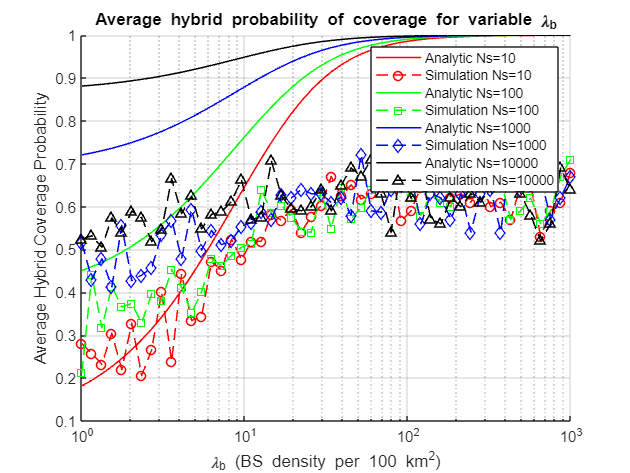


%% Plot the results
figure;
hold on;
colors = {'r', 'g', 'b', 'k'};
markers = {'o', 's', 'd', '^'};

% for idx_Ns = 1:length(Ns_list)
%     Ns = Ns_list(idx_Ns);
%     plot(bs_density_per_100km2, p_c_analytic(idx_Ns,:), ['-', colors{idx_Ns}], 'DisplayName', ['Analytic Ns=', num2str(Ns)]);
%     plot(bs_density_per_100km2, p_c_simulation(idx_Ns,:), ['--', colors{idx_Ns}, markers{idx_Ns}], 'DisplayName', ['Simulation Ns=', num2str(Ns)]);
% end

for idx_Ns = 1:length(Ns_list)
    Ns = Ns_list(idx_Ns);
    plot(bs_density_per_100km2, p_c_analytic(idx_Ns,:), ['-', colors{idx_Ns}], 'LineWidth', 1, ...
        'DisplayName', ['Analytic Ns=', num2str(Ns)]);
    plot(bs_density_per_100km2, p_c_simulation(idx_Ns,:), ['--', colors{idx_Ns}, markers{idx_Ns}], ...
        'LineWidth', 1, 'DisplayName', ['Simulation Ns=', num2str(Ns)]);
end


set(gca, 'XScale', 'log');
xlabel('\lambda_b (BS density per 100 km^2)');
ylabel('Average Hybrid Coverage Probability');
title('Average hybrid probability of coverage for variable \lambda_b');
legend('show');
grid on;

function [x, y] = generate_uniform_circle(N, radius)
    % Generate N random points uniformly distributed within a circle of given radius
    theta = 2 * pi * rand(N,1);
    r = radius * sqrt(rand(N,1));
    x = r .* cos(theta);
    y = r .* sin(theta);
end

% (Include all your function definitions here, same as before)
function l = compute_l(phi, l_o, R_earth, h)
    d = sqrt(R_earth^2 + (R_earth + h)^2 - 2 * R_earth * (R_earth + h) * cos(phi));
    l = l_o ./ d.^2;
end

function E_zeta = compute_E_zeta(R_earth, h, phi, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS)
    rho = log(10)/10;
    alpha = R_earth / (R_earth + h);
    cot_theta = sin(phi + eps) ./ (cos(phi) - alpha);
    p_LoS = exp(-beta * cot_theta);
    p_LoS = min(max(p_LoS, 0), 1);
    p_NLoS = 1 - p_LoS;
    E_zeta = p_LoS .* exp((rho^2 * sigma_LoS^2) / 2 - rho * mu_LoS) + p_NLoS .* exp((rho^2 * sigma_NLoS^2) / 2 - rho * mu_NLoS);
end

function f_phi = compute_f_phi(phi, Ns)
    f_phi = (Ns / 2) * sin(phi) .* exp(- (Ns / 2) * (1 - cos(phi)));
end

function F_zeta = compute_F_zeta(R_earth, h, x, phi, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS)
    rho = log(10)/10;
    alpha = R_earth / (R_earth + h);
    cot_theta = sin(phi + eps) ./ (cos(phi) - alpha);
    p_LoS = exp(-beta * cot_theta);
    p_LoS = min(max(p_LoS, 0), 1);
    p_NLoS = 1 - p_LoS;
    arg_LoS = (10 * log10(x) + mu_LoS) / (sqrt(2) * sigma_LoS);
    arg_NLoS = (10 * log10(x) + mu_NLoS) / (sqrt(2) * sigma_NLoS);
    F_zeta = 0.5 + (p_LoS / 2) .* erf(arg_LoS) + (p_NLoS / 2) .* erf(arg_NLoS);
end

function y = integrand_p_s(phi, Ns, P, gamma_o, W_s, l_o, R_earth, h, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS, I_s)
    l = compute_l(phi, l_o, R_earth, h);
    f_phi = compute_f_phi(phi, Ns);
    x = gamma_o * (I_s + W_s) ./ (P * l);
    F_zeta = compute_F_zeta(R_earth, h, x, phi, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS);
    y = (1 - F_zeta) .* f_phi;
end

function p_s = compute_p_s(Ns, P, gamma_o, W_s, l_o, R_earth, h, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS, D, lambda_d, kappa_s)
    alpha = R_earth / (R_earth + h);
    phi_m = acos(alpha);
    % Compute average interference power
    I_s_avg = compute_I_s(Ns, P, l_o, R_earth, h, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS, D, lambda_d, kappa_s);
    integrand = @(phi) integrand_p_s(phi, Ns, P, gamma_o, W_s, l_o, R_earth, h, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS, I_s_avg);
    p_s = integral(integrand, 0, phi_m);
end

function I_s = compute_I_s(Ns, P, l_o, R_earth, h, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS, D, lambda_d, kappa_s)
    alpha = R_earth / (R_earth + h);
    phi_m = acos(alpha);
    % Integrate over phi to compute average interference
    integrand = @(phi) kappa_s * P * compute_l(phi, l_o, R_earth, h) .* compute_E_zeta(R_earth, h, phi, beta, mu_LoS, sigma_LoS, mu_NLoS, sigma_NLoS) .* sin(phi);
    integral_result = integral(integrand, 0, phi_m);
    I_s = D * lambda_d * 2 * pi * R_earth^2 * integral_result;
end

function p_b = compute_p_b(lambda_b, P, gamma_o, W_b, l_o, a, D, lambda_d, kappa_b)
    r_max = 10000;  % Maximum integration limit in meters
    integrand = @(r) integrand_p_b(r, lambda_b, P, gamma_o, W_b, l_o, a, D, lambda_d, kappa_b);
    p_b = integral(integrand, 0, r_max);
end

function I_s_avg = compute_I_s_avg(P, l_o, R_earth, h, beta, mu_LoS_dB, sigma_LoS_dB, mu_NLoS_dB, sigma_NLoS_dB, D, lambda_d, kappa_s)
    alpha = R_earth / ( R_earth + h );
    phi_m = acos( alpha );
    % Define the integrand
    integrand = @(phi) kappa_s * P * compute_l( phi, l_o, R_earth, h ) .* compute_E_zeta( R_earth, h, phi, beta, mu_LoS_dB, sigma_LoS_dB, mu_NLoS_dB, sigma_NLoS_dB ) .* sin( phi );
    % Compute the integral
    I = integral( integrand, 0, phi_m);
    % Compute I_s_avg
    I_s_avg = 2 * pi * R_earth^2 * D * lambda_d * I;
end

function y = integrand_p_b(r, lambda_b, P, gamma_o, W_b, l_o, a, D, lambda_d, kappa_b) %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%where is b?
    s = gamma_o * r.^a ./ (P * l_o);
    L_Ib = exp(- pi * D * lambda_d * ((kappa_b * P * l_o * s).^(2/a)) / sinc(2 / a));
    expo = exp(- gamma_o * r.^a * W_b ./ (P * l_o));
    f_Ro = 2 * pi * lambda_b * r .* exp(- pi * lambda_b * r.^2);
    y = L_Ib .* expo .* f_Ro;
end
